Set the initial conditions.

[a, e, i, w, O, theta] = deal(50000e3, 0.01, 90*pi/180, 3*pi/4, 70*pi/180, 0);
[p, f, g, h, k, L] = class2mod(a, e, i, w, O, theta);
mod_param0 = [p, f, g, h, k, L];
mu = 3.986004418e14; % m3 s-2. Earth's gravitational parameter
sat_mass = 1e2; % kg
area = 2000; % m^2
ref = 1;

Create functions for the simulation.

jdate = @(t) juliandate(datetime('today') + seconds(t));
rad_pressure = @(t,prmt) radiation_pressure(prmt,jdate(t),area,ref);
sys = @(t,prmt) orbital_system(t, prmt, mu, rad_pressure(t,prmt)./sat_mass);
% sys = @(t,prmt) orbital_system(t, prmt, mu, [0 0 0]');
tf = 1e7;

Simulate

opts = odeset(MaxStep=1e4);
[t, mod_param] = ode45(sys,[0 tf], mod_param0, opts);

[p, f, g, h, k, L] = unpack(mod_param);
[x, y, z] = mod2XCI(p, f, g, h, k, L);

Calculations for vectors.

pos = 1;
[u, v, w] = mod2VCI(p(pos), f(pos), g(pos), h(pos), k(pos), L(pos), mu);
mult = 10000; u=u*mult; v=v*mult; w=w*mult;
rfv = radiation_pressure([p(pos), f(pos), g(pos), h(pos), k(pos), L(pos)],...
    jdate(0),area,ref)*1000000000;
rfv_lvlh = CI2LVLH(rfv,[x(pos),y(pos),z(pos)]',[u v w]')

rfv_lvlh = 1.0e+07 *

    1.4828
    1.1441
   -0.1244


esp = -planetEphemeris(jdate(0),'Sun','Earth','432t','km')';

Barebones visualisation.

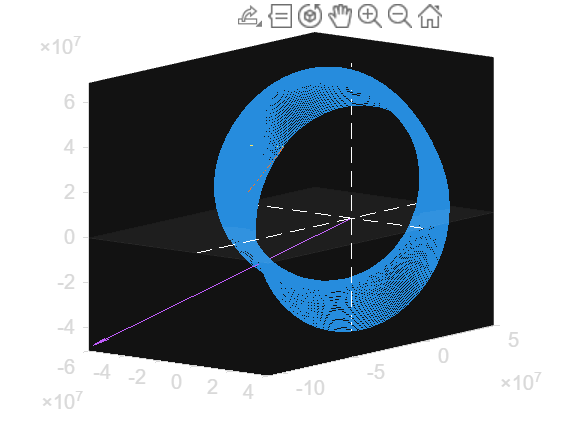

figure(1)
clf
plot3(x, y, z, '-')
hold on
quiver3(x(pos),y(pos),z(pos), u,v,w)
quiver3(x(pos),y(pos),z(pos), rfv(1),rfv(2),rfv(3))
% ^ este vector no está en el sistema correcto si no se modifica la función
quiver3(0,0,0, esp(1),esp(2),esp(3))
axisPlot(1,'w')
planeXY(1,'w')
daspect([1 1 1])

Visualisation.

t0 = datetime('today')

t0 = datetime
   27-Nov-2023


tfin = t0 + seconds(tf);
sample_time = 60;
positionsTT = timetable([x y z], RowTimes=seconds(t));
sc = satelliteScenario(t0,tfin,sample_time);
sat = satellite(sc,positionsTT,Name = "Spacecraft");

v = satelliteScenarioViewer(sc,CameraReferenceFrame = "Inertial", Basemap='darkwater');